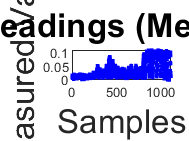

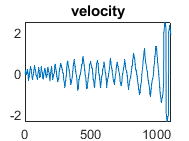

clc;
clear;

%% Loading the data in matlab
data = load("magnets-data.txt");
actual_position = data(:,1);
actual_velocity = data(:,2);
sensor_reading = data(:,3);

%% Plotting the measurements
figure
t = 1:1:length(data);
plot(t,sensor_reading,'.b')
title('Sensor Readings (Measurements)',FontSize=20)
ylabel('Measured Value',FontSize=20);
xlabel('Samples',FontSize=20);


%% Given Constants
sigma_a = 0.0625;
sigma_m = 4;
sigma_n = 0.003906;
x_m1 = -10;
x_m2 = 10;

%% Initial states
x=sensor_reading(1);
xdot=0;

%% Initalizing particles
M = 1000;
w(1:M,1) = 1/M;

%% initial states of the particles
xP(1:M,1) = x;
xdotP(1:M,1) = xdot;

%% Particle Filter Loop

i = 0; j = 0;
for i = 2:1:length(data)

    %% Actual Measurement
    yt = sensor_reading(i);
    
    for j = 1:1:M

        %% Propagation through state transition eqns
        xP(j,2) = xP(j,1) + xdotP(j,1)*1;
        if xP(j,1) < -20
            xdotP(j,2) = 2;
        elseif xP(j,1) >= -20 && xP(j,1) < 0
            xdotP(j,2) = xdotP(j,1) + abs(normrnd(0,sigma_a));
        elseif xP(j,1) >= 0 && xP(j,1) <= 20
            xdotP(j,2) = xdotP(j,1) - abs(normrnd(0,sigma_a));
        elseif xP(j,1) > 20
            xdotP(j,2) = -2;
        end
        
        %% Calculting weights
        y(j,2) = (1/(sigma_m*sqrt(2*pi)))*(exp(-((xP(j,2)-x_m1)^2)/(2*(sigma_m^2)))) + (1/(sigma_m*sqrt(2*pi)))*(exp(-((xP(j,2)-x_m2)^2)/(2*(sigma_m^2))));
        p(j,2) = (1/(sigma_n*sqrt(2*pi)))*(exp(-((y(j,2)-yt)^2)/(2*(sigma_n^2))));
        w_tilda(j) = w(j,1)*p(j,2);
    end

    %% Normalizing weights
     w(:,2) = w_tilda./sum(w_tilda);

    %% Expected Value
    exP = 0;
    exP = xP(:,2).*w(:,2);
    
    Ex(i,1) = sum(exP);
    
    %%  Resampling
    for j = 1:M
        v(j) = ((M*w(j,2))-1)^2;
    end
    cv = (1/M)*sum(v);
    ESS = M/(1+cv);
    
    if ESS < 0.5*M
        fprintf('Resampling %d \n', i);
        Q=cumsum(w(:,2)); 
        t=rand(M+1); 
        T=sort(t); 
        T(M+1)=1.0; 
        l=1; k=1;
        while (k<=M)
            if (T(k) < Q(l))
                Index(k)=l;
                k=k+1;
            else
                l=l+1;
            end 
        end 

        for o=1:1:M
            NewP(o,1)=xP(Index(o));
            NewV(o,1)=xdotP(Index(o));
            NewW(o,1)=1/M;
        end 
        xP(:,2) = NewP(:,1);
        xdotP(:,2) = NewV(:,1);
        w(:,2) = NewW(:,1);
    end
    xP(:,1) = xP(:,2);
    xdotP(:,1) = xdotP(:,2);
    w(:,1) = w(:,2);
end

Resampling 31 
Resampling 42 
Resampling 54 
Resampling 65 
Resampling 77 
Resampling 83 
Resampling 89 
Resampling 98 
Resampling 104 
Resampling 106 
Resampling 110 
Resampling 122 
Resampling 131 
Resampling 136 
Resampling 144 
Resampling 158 
Resampling 161 
Resampling 170 
Resampling 182 
Resampling 193 
Resampling 201 
Resampling 203 
Resampling 211 
Resampling 219 
Resampling 228 
Resampling 236 
Resampling 239 
Resampling 241 
Resampling 245 
Resampling 256 
Resampling 260 
Resampling 262 
Resampling 273 
Resampling 275 
Resampling 279 
Resampling 284 
Resampling 285 
Resampling 291 
Resampling 294 
Resampling 297 
Resampling 298 
Resampling 306 
Resampling 309 
Resampling 312 
Resampling 315 
Resampling 316 
Resampling 318 
Resampling 320 
Resampling 322 
Resampling 323 
Resampling 327 
Resampling 332 
Resampling 336 
Resampling 338 
Resampling 339 
Resampling 341 
Resampling 343 
Resampling 345 
Resampling 347 
Resampling 348 
Resampling 350 
Resampling 352 
Resampling 356 


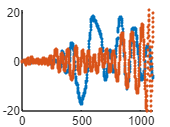


%% Plotting the estimated position values
figure
t = 1:1:length(data);
scatter(t,Ex,'.')
hold on
scatter(t,actual_position,'.');